clear; clc; close all;

% DH-parametre
% DH-parametre
syms theta_1 theta_2 theta_3 theta_4 theta_5

[alpha_1, alpha_4] = deal(-pi/2, pi/2);
[alpha_2, alpha_3, alpha_5] = deal(0);
[a1, a2, a3, a4, a5] = deal(0, 0.35, 0.30, 0, 0);
[d1, d2, d3, d4, d5] = deal(0.2, 0, 0, 0.2, 0.05);

%      [theta d a alpha sigma]
L1 = Link([0 d1 a1 alpha_1 0]);
L2 = Link([0 d2 a2 alpha_2 0]);
L3 = Link([0 d3 a3 alpha_3 0]);
L4 = Link([0 d4 a4 alpha_4 0]);
L5 = Link([0 d5 a5 alpha_5 0]);
L2.offset = -pi/2;
L4.offset = pi/2;

% Sett sammen leddene til et SerialLink-objekt
robot = SerialLink([L1 L2 L3 L4 L5], 'name', '5DOF');

% Håv/end-effektor
robot.tool = transl(0,0,0.20); % Håven stikker 20 cm ut fra håndleddet

R_align = [ 0  0  1;   % col1 = x_tool = +Y_world
            1  0  0;   % col2 = y_tool = +Z_world
            0  1  0];  % col3 = z_tool = +X_world (håv-retning)

P_goal = [0.45; 0.30; -0.30];

% Full ønsket pose (posisjon + orientering)
T_goal = transl(P_goal') * r2t(R_align);

mask = [1 1 1 0 0 1]; % Samme idé som i håv-sveip-skriptet

q0 = [0 0 0 0 0]; % Startgjetning

% Invers kinematikk
q_sol = robot.ikine(T_goal, q0, 'mask', mask);

q_sol = q_sol(:)';

% Forward kinematics
T_sol = robot.fkine(q_sol).T;
p_sol = T_sol(1:3,4);
p_err = norm(p_sol - P_goal);

% Verifiser orientering ved å sjekke z_tool-retningen
z_tool_sol = T_sol(1:3,3); % Kolonne 3 = Z-akse til tool i world
z_tool_des = R_align(1:3,3);
angle_err  = acos( max(-1,min(1, z_tool_sol.' * z_tool_des))); % Vinkel mellom dem

fprintf('Ønsket posisjon    : [%.3f  %.3f  %.3f] m\n', P_goal);

Ønsket posisjon    : [0.450  0.300  -0.300] m


fprintf('Oppnådd posisjon   : [%.3f  %.3f  %.3f] m\n', p_sol);

Oppnådd posisjon   : [0.450  0.300  -0.300] m


fprintf('Posisjonsfeil      : %.4g m\n', p_err);

Posisjonsfeil      : 1.665e-16 m


fprintf('Vinkelfeil         : %.4g°\n', angle_err);

Vinkelfeil         : 1.472°


fprintf('Leddvinkler (rad)  : [%.3f  %.3f  %.3f  %.3f  %.3f]\n', q_sol);

Leddvinkler (rad)  : [0.209  1.513  1.188  0.340  1.760]


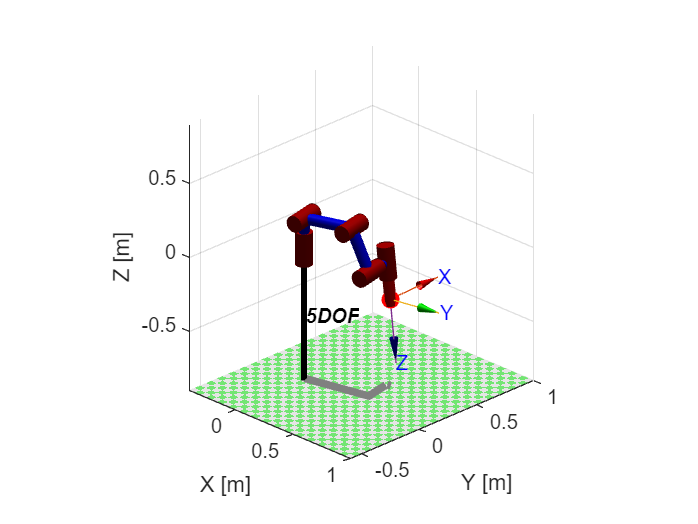


% Plot resultat
figure('Color','w');
robot.plot(q_sol, 'workspace', [-0.4 1.0 -0.6 1.0 -0.9 0.9], 'scale', 0.8);
hold on; grid on;
scatter3(P_goal(1), P_goal(2), P_goal(3), 80, 'r', 'filled');
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
view(45,25);